
elev = zeros(240, 1);
azi = zeros(240,1);
i =0;
for pol = -30:210
    i = i+1;
    [azi(i),elev(i)]=hor2sph(0,pol);
end
elev = floor(elev);
 


clear all; clc; 
[phi,theta,L] = getLebedev(2)

phi =      0    45   135   225   315     0    90   180   270    45   135   225   315    18    72   108   162   198   252   288   342     0    45    90   135   180   225   270   315    18    72   108   162   198   252   288   342    45   135   225   315     0    90   180   270    45   135   225   315     0


theta =     90    65    65    65    65    45    45    45    45    35    35    35    35    18    18    18    18    18    18    18    18     0     0     0     0     0     0     0     0   -18   -18   -18   -18   -18   -18   -18   -18   -35   -35   -35   -35   -45   -45   -45   -45   -65   -65   -65   -65   -90


L =          0    1.5708
    0.7854    1.1345
    2.3562    1.1345
    3.9270    1.1345
    5.4978    1.1345
         0    0.7854
    1.5708    0.7854
    3.1416    0.7854
    4.7124    0.7854
    0.7854    0.6109


ls_dirs(:,1) = phi;
ls_dirs(:,2) = theta;
ls = ls_dirs;
[ls_groups, mesh] = findLsTriplets(ls_dirs);


[vert(:,1), vert(:,2), vert(:,3)] = sph2cart(L(:,1), L(:,2), 1);
DT = delaunayTriangulation(vert(:,1), vert(:,2), vert(:,3))

DT =   delaunayTriangulation with properties:

              Points: [50×3 double]
    ConnectivityList: [117×4 double]
         Constraints: []


C = convexHull(DT)

C =      1     2     3
     1     3     4
     1     4     5
     1     5     2
     2     5     6
     2     6    10
     2     7     3
     2    10     7
     3     7    11
     3     8     4


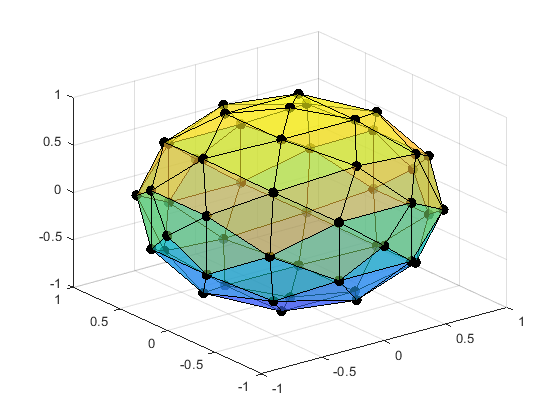


figure(1)
H = trisurf(C,vert(:,1), vert(:,2), vert(:,3),'FaceAlpha',0.6,'Marker','o','MarkerFaceColor','black','MarkerSize',7);

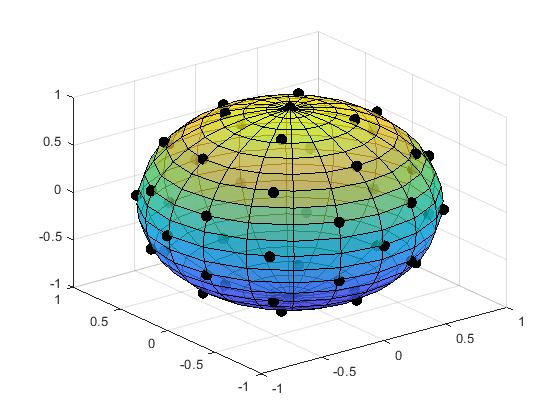


layoutInvMtx = invertLsMtx(ls_dirs, ls_groups);
aziRes = 5;
elevRes = 5;
[Elev, Azi] = meshgrid(-90:elevRes:90, 0:aziRes:360);
src_dirs3D = [Azi(:) Elev(:)];
% Get VBAP gains
gains3D = vbap(src_dirs3D, ls_groups, layoutInvMtx);

figure(2)
[x,y,z] =sphere;
radius = 0.99;
x = x * radius;
y = y * radius;
z = z * radius;

surf(x,y,z,'FaceAlpha',0.7)
hold on
scatter3(vert(:,1),vert(:,2),vert(:,3),60,'black', 'MarkerFaceColor','black')
hold off